# **Amplititude-shift keying trasmitter**

% ************************************************************************
% Author: CONG LI
% Date Created: 2023
%
% This script is part of a course project for 
% Communication Systems: Theory and Measurement M
% at University of Bologna.
% ************************************************************************
clear all % clear all varables
close all % close all plots
clc % clear the screen in the command window
warning('off','all')


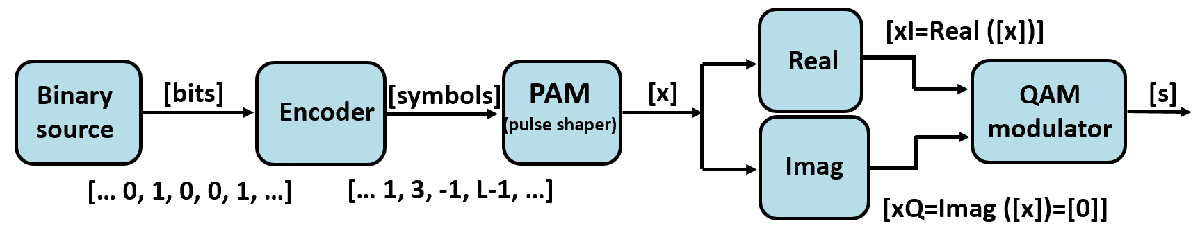

ASK is an amplitude modulation that tranform digital data to fixed-amplitude carrier wave at fixed frequency.The picture above shows the inplemented system process. Binary source is encoded form bits to symbols by encouder and shaped into viarous amplitude pluse by PAM. L-ASK singals do not have any in quadrature components, So take the output of PAM and feed it into the QAM in-phase signal input of the QAM modulation system.This is the inplemented modulation system.

** Setting signal specifications**

%----------------------------------------------------------------
% *Signal specifications*
bits_per_symbol=4; % number of bits that correspond to a symbol
L=2^bits_per_symbol; % number of levels of the modulation alphabet
nbits=1000*bits_per_symbol; % number of bits to be transmitted
Br=1000; % [bits/s] bit rate
fs=50000; % [samples/s] sampling frequency
fc=3000; % [Hz] carrier frequency
Bs=Br/log2(L); % [symbols/s] Symbol rate
nsps=fs/Bs; % samples per symbol
%----------------------------------------------------------------

**The Pluse shaper**

we have two different plusetypes **ROOTRAISEDCOSINE** and **RECT**

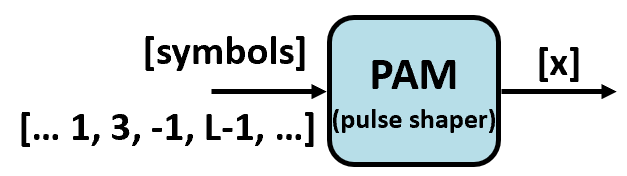

% *Pulse shaper specifications*
Nf=5*nsps; % number of filter coefficients (=five time the symbol duration)
pulsetype='RECT'; % pulsetype: 'RECT' or 'ROOTRAISEDCOSINE'
switch pulsetype
case 'ROOTRAISEDCOSINE'
rolloff=0.8; % roll-off factor for root raised cosine pulses
bandwidth_Hz=0.5*Bs*(1+rolloff) % bandwidth of the baseband signal
case 'RECT'
rolloff=[];
bandwidth_first_lobe_Hz=Bs;
end

**Binary source**

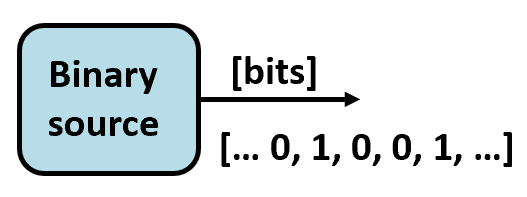

The function BinarySource_2023() using Matlab function randi generate 1 by nbits matrix to describe the binary source

%----------------------------------------------------------------
% *Source bits generation*
source_bits=BinarySource_2023(nbits); % vector with the source bits

**Encoder**

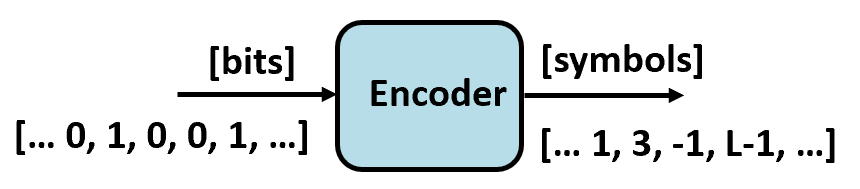

The Encoder_2023() function given as input a victior of bit source bits, generate as output a victior of symbols using the multi-level symmetric alphabet {-1,1,-3,3... -L+1,L-1}  of L=nlevels levels(L=2,4,8),according the Gray rule.

%----------------------------------------------------------------
% *Symbols generation with Gray mapping*
symbols=Encoder_2023(source_bits, L);

bit_table =      0     0     0     0
     0     0     0     1
     0     0     1     1
     0     0     1     0
     0     1     1     0
     0     1     1     1
     0     1     0     1
     0     1     0     0
     1     1     0     0
     1     1     0     1


symbol_table =    -15
   -13
   -11
    -9
    -7
    -5
    -3
    -1
     1
     3


**Plot of the constellation**

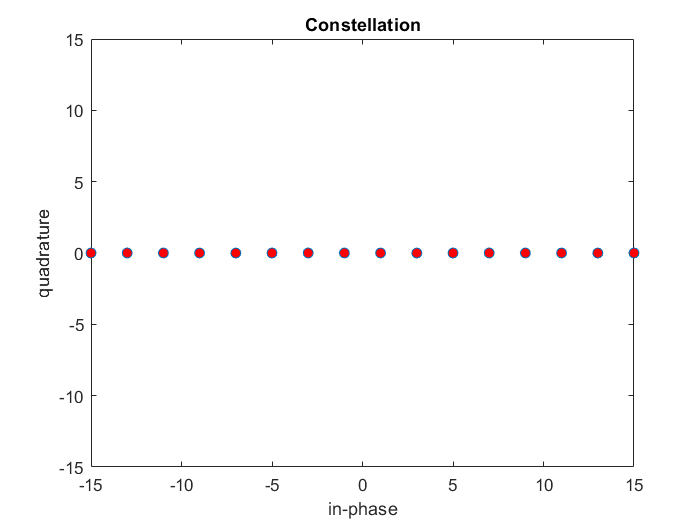

%----------------------------------------------------------------
% *Plot of the constellation*
figure
plot(real(symbols),imag(symbols),'o','MarkerFaceColor','r'),
axis ([-L+1 L-1 -L+1 L-1]);
title('Constellation');
xlabel('in-phase');
ylabel('quadrature');

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse or RECT pluse, rolloff=0.8 or 0.2    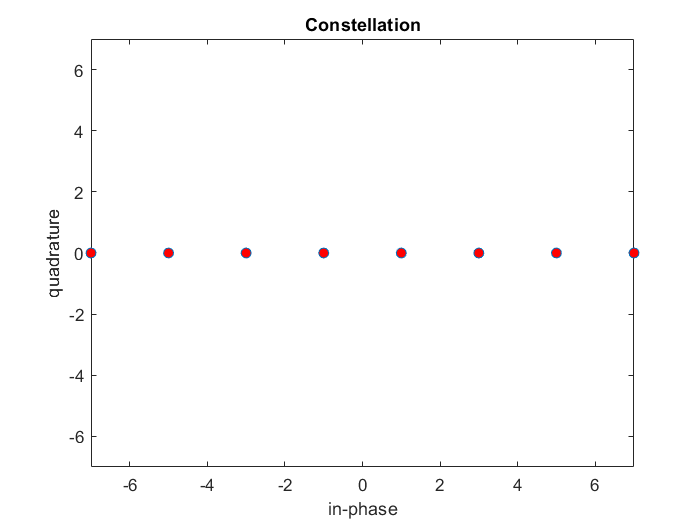

This picture is plotteed with parameter L = 8, ROOTRAISEDCOSINE pluse or RECT pluse, rolloff=0.8 or 0.2    

This picture is plotteed with parameter L = 16, ROOTRAISEDCOSINE pluse or RECT pluse, rolloff=0.8 or 0.2                                                                      

These pictures above show the constellation of QAM signals, with x-axis representing in phase signals and y-axis representing quadrature signals, which leads to the conclusion that L-ASK signals do not have any quadrature components.It can be concluded the constellation demostrates the change of L.

**Generation of the baseband PAM signal**

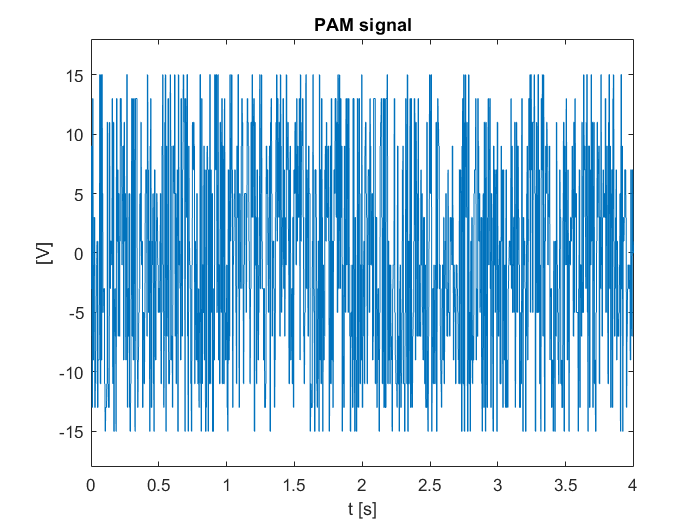

%----------------------------------------------------------------
% *Generation of the baseband PAM signal*
x=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff);
Ts=1/fs;% sampling interval
T=Ts*(length(x)-1); % signal duration
%----------------------------------------------------------------
% *Plot of the baseband PAM signal and of its spectrum*
figure
t=0:1/fs:T;
plot(t,x)
xlabel('t [s]')
ylabel ('[V]')
title('PAM signal')
axis([min(t) max(t) 1.2*min(x) 1.2*max(x)])

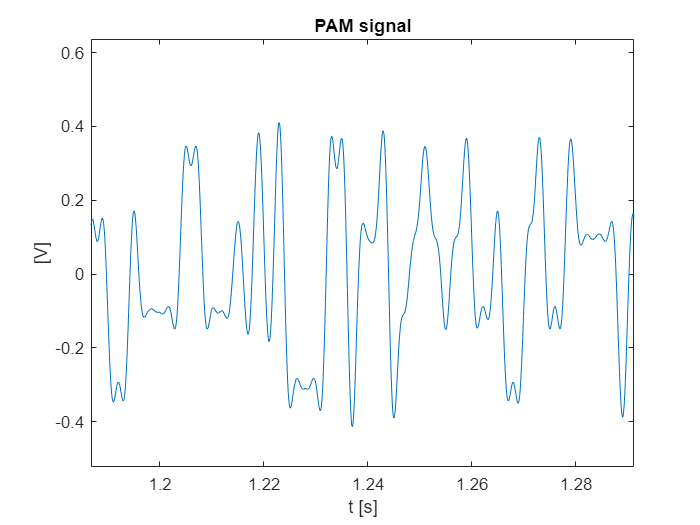

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.8         

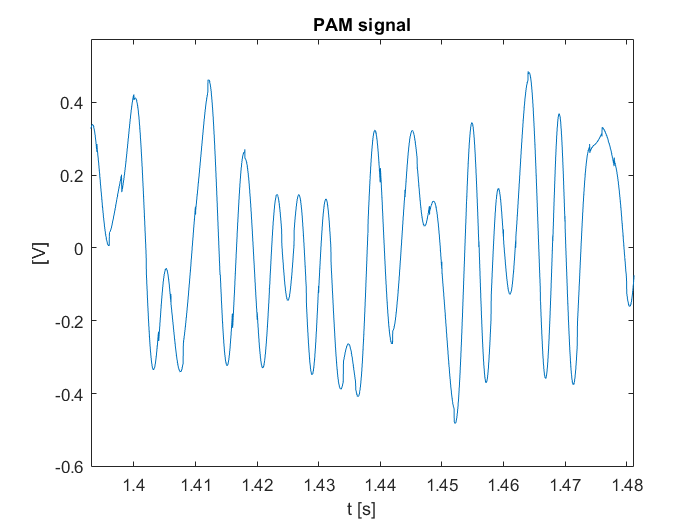

This picture is plotteed with parameter L = 4 ROOTRAISEDCOSINE pluse, rolloff=0.2         

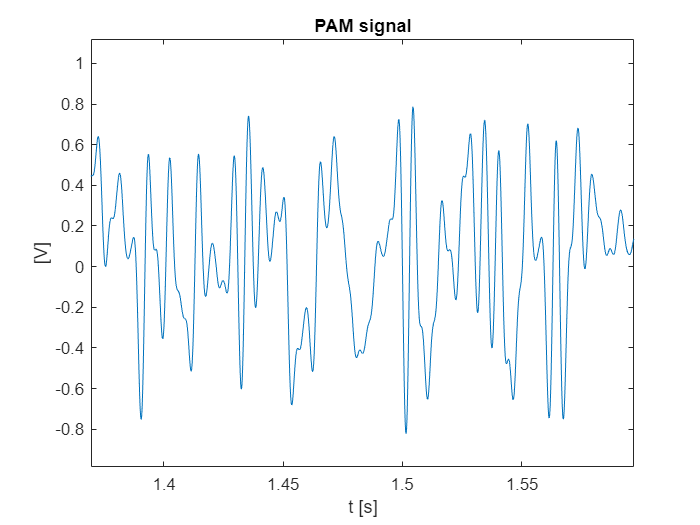

This picture is plotteed with parameter L = 8, ROOTRAISEDCOSINE pluse , rolloff=0.8          

l=8 root         0.8        

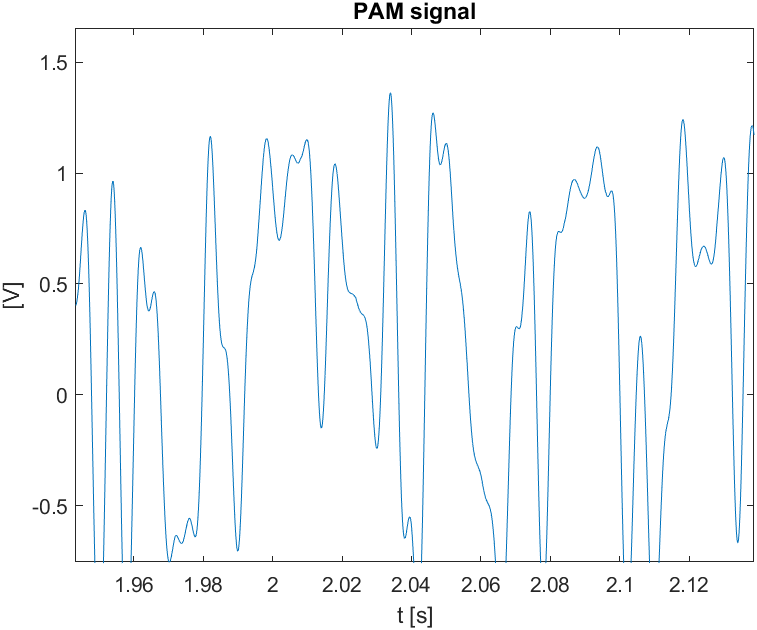

This picture is plotteed with parameter L = 16, ROOTRAISEDCOSINE pluse , rolloff=0.8   

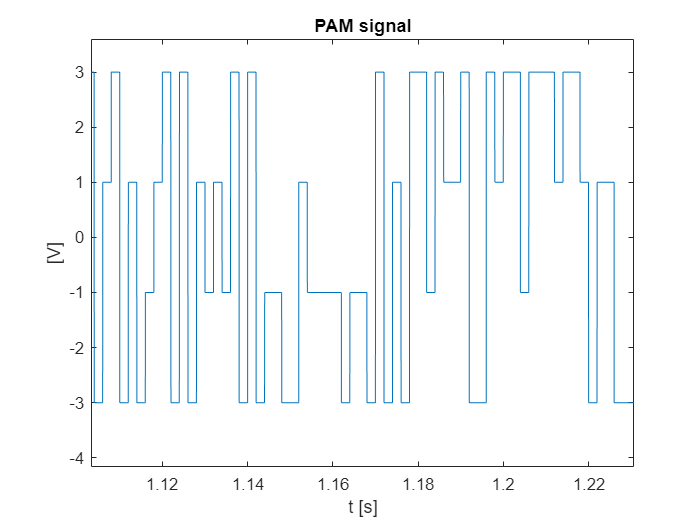  

This picture is plotteed with parameter L = 4,  RECT pluse

These picture illustrated the symbols sequences with different parameters L=4,8,16, RECT or ROOTRAISEDCOSINE pluse shape and different values of the roll-off factor (0< α < 1) for the ROOTRAISEDCOSINE pulse. In the case L parameter is different and the other parameters are the same, the larger value L is, the larger magnitude of a symbol is. In the case rolloff parameter is different and the other parameters are the same, the larger value rolloff is, the more pluse shape tends to rectgular.  

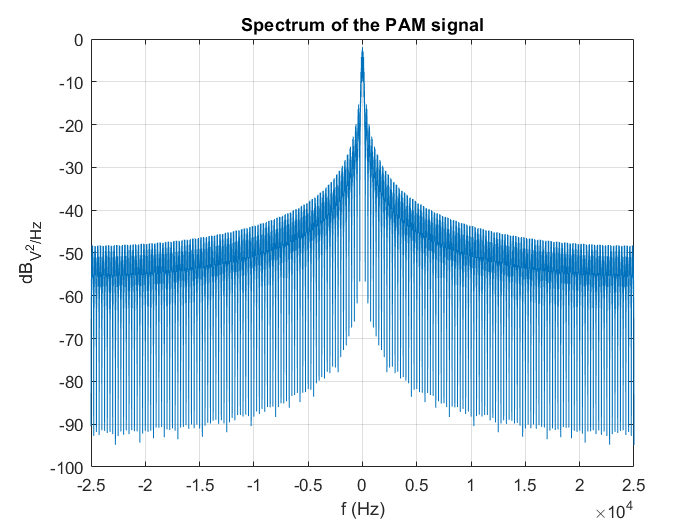

figure
PlotSpectrum_2023(x,fs);
title('Spectrum of the PAM signal')

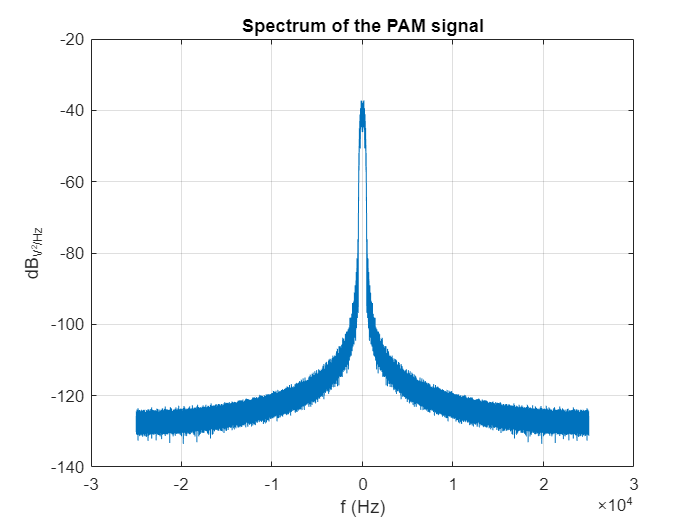

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.8   

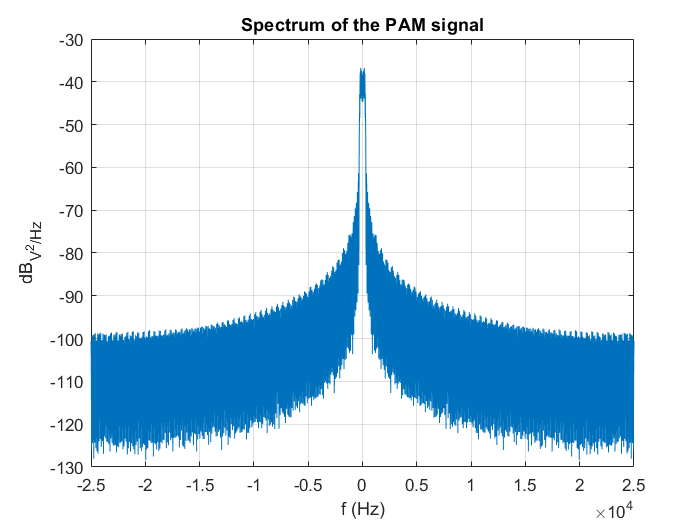

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.2

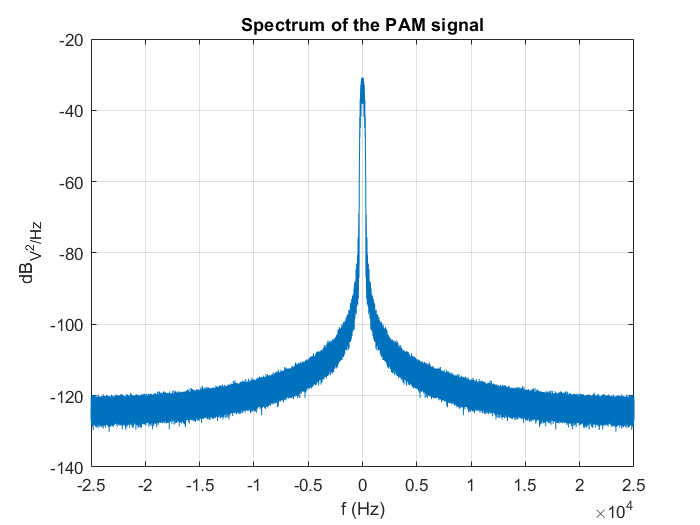

This picture is plotteed with parameter L = 8, ROOTRAISEDCOSINE pluse , rolloff=0.8   

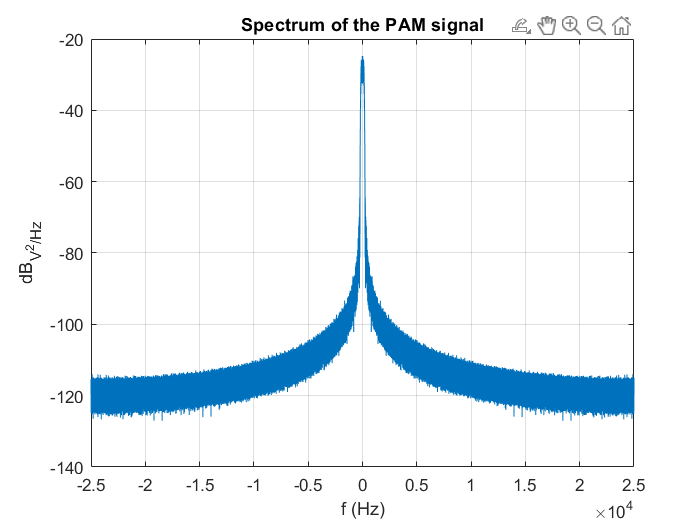

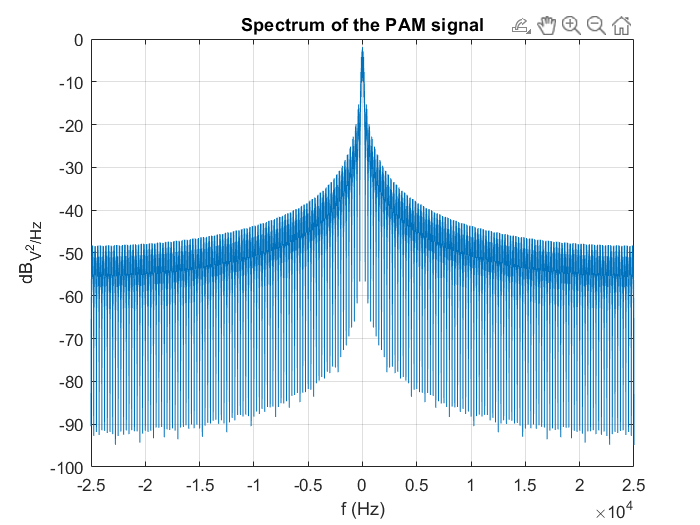

This picture is plotteed with parameter L = 16, ROOTRAISEDCOSINE pluse , rolloff=0.8   

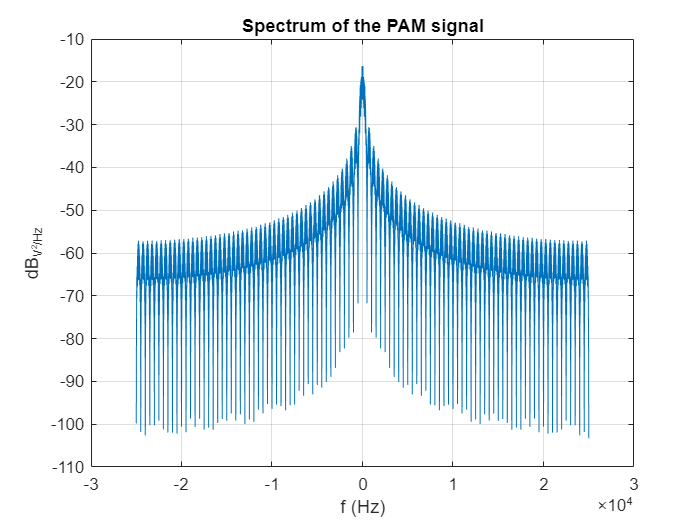

This picture is plotteed with parameter L = 4, RECT pluse  

In frequency domain, the value of L have impact on signal gain, the larger value L is, the lower modulation gain is. This is beacuse symbols have a higher value need more energy. Raising the value of rolloff can effectively decerase the gain in the other frequency.The RECT pluse have a lower gain at 0 frequency and higher gain at other frequency.

**QAM modulator**

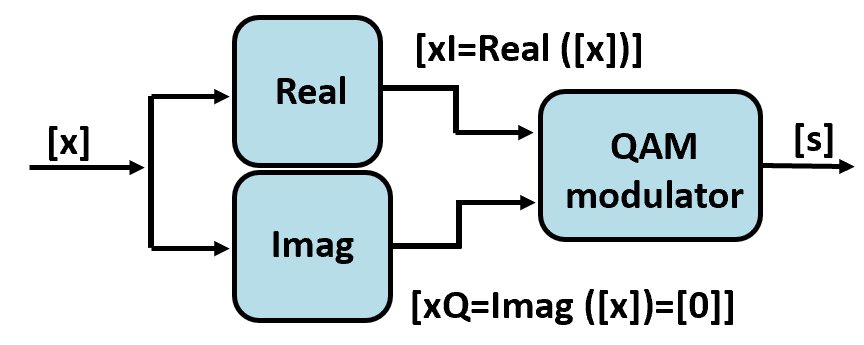

% *L-ASK modulation through the QAM modulator*
xI=x % in-phase signal

xI =     -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


xQ=zeros(1,length(x)) % the quadrature component is zero

xQ =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


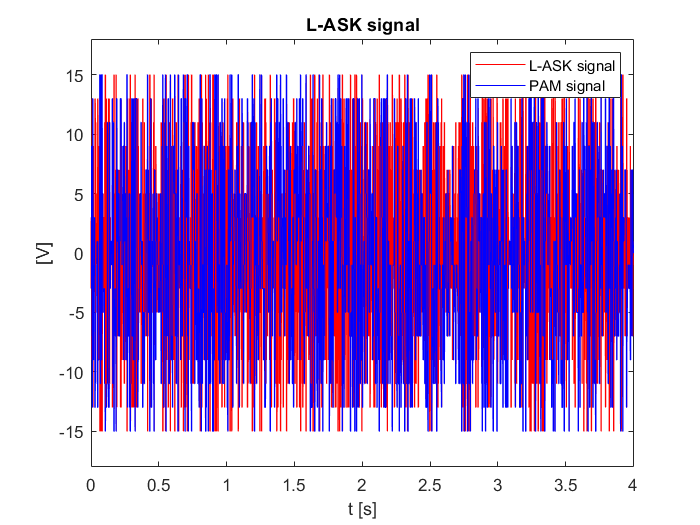

s=ModQAM_2023(xI,xQ,fc,T,fs);
%----------------------------------------------------------------
% *Plot of the L-ASK signal and of its spectrum*
figure
plot(t,s,'r')
hold on
plot(t,x,'b')
axis([min(t) max(t) 1.2*min(x) 1.2*max(x)])
xlabel('t [s]')
ylabel ('[V]')
title('L-ASK signal')
legend('L-ASK signal','PAM signal')

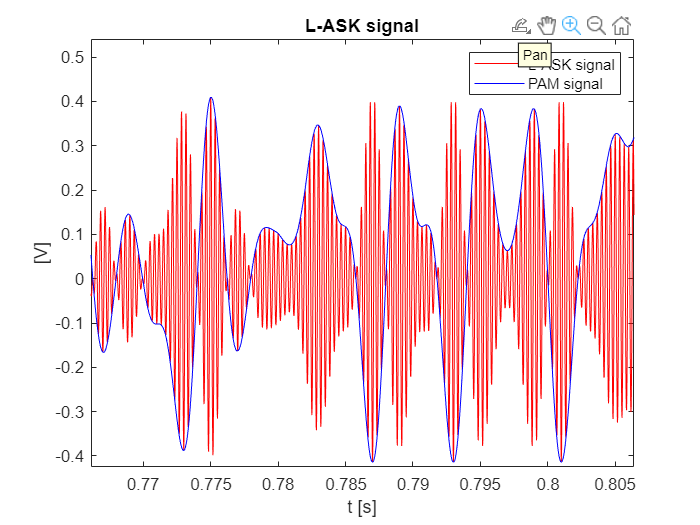

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.8          

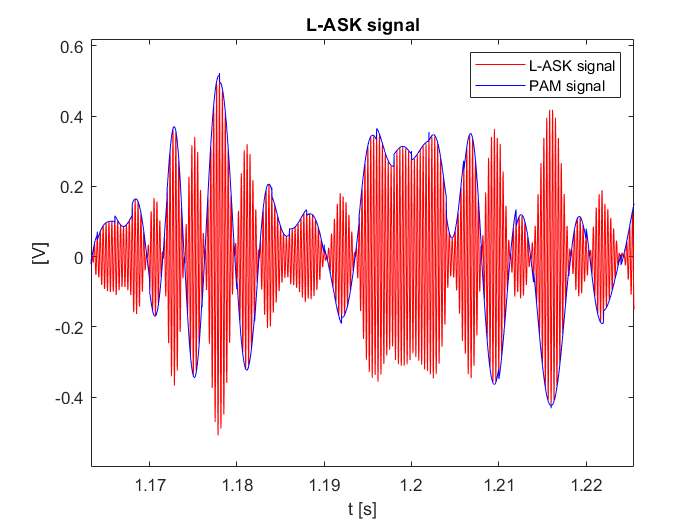

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.2          

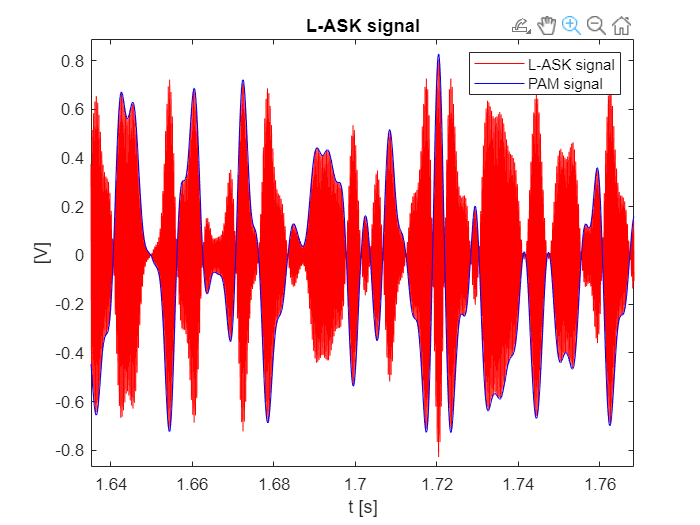

This picture is plotteed with parameter L = 8, ROOTRAISEDCOSINE pluse , rolloff=0.8          

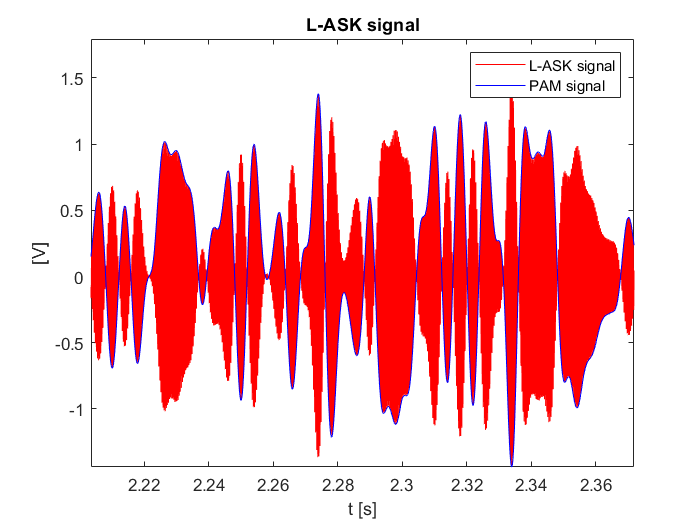

This picture is plotteed with parameter L = 16, ROOTRAISEDCOSINE pluse , rolloff=0.8          

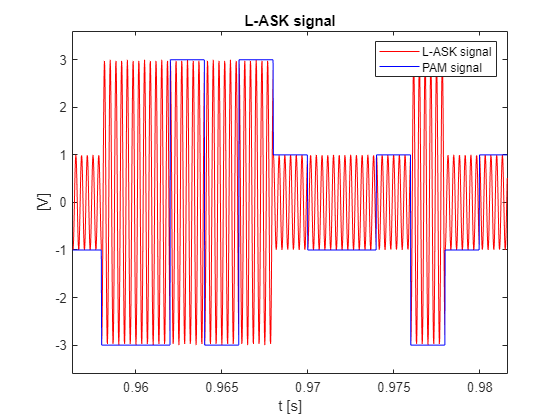

This picture is plotteed with parameter L = 4, RECT pluse

These pictures show the symbols sequence which is the combination of the PAM signals, and the results are similar to PAM signals.

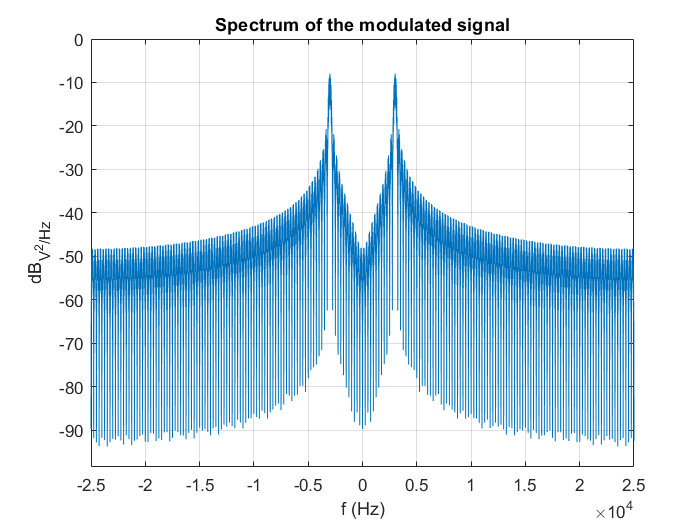

figure
PlotSpectrum_2023(s,fs);
title('Spectrum of the modulated signal')

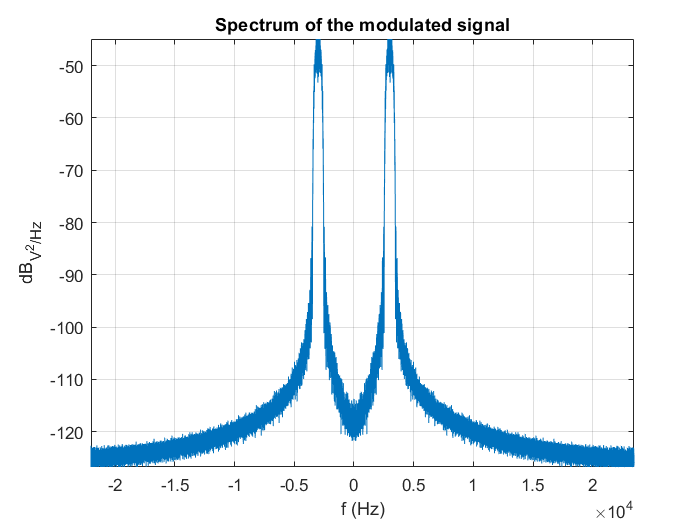

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.8          

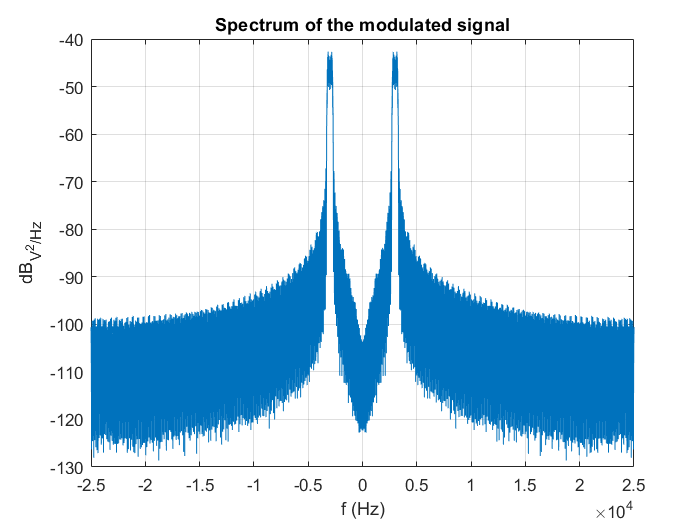

This picture is plotteed with parameter L = 4, ROOTRAISEDCOSINE pluse , rolloff=0.2         

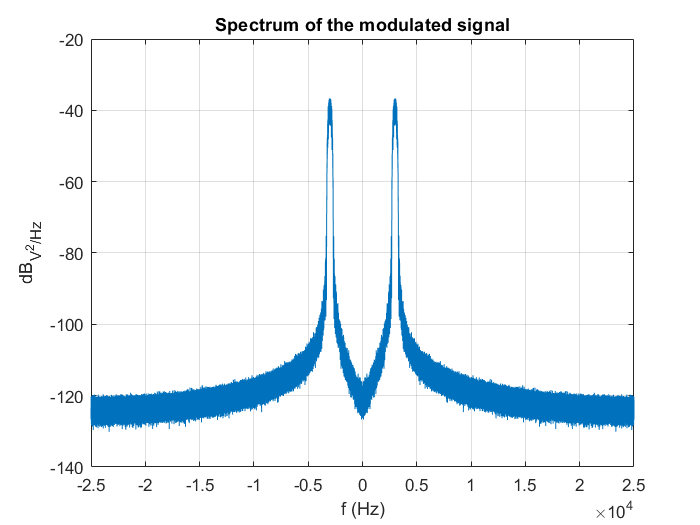

This picture is plotteed with parameter L = 8, ROOTRAISEDCOSINE pluse , rolloff=0.8   

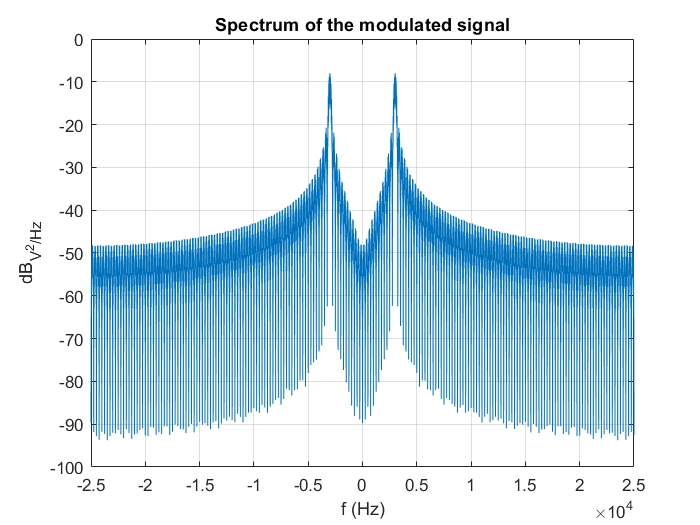

This picture is plotteed with parameter L = 16, ROOTRAISEDCOSINE pluse , rolloff=0.8   

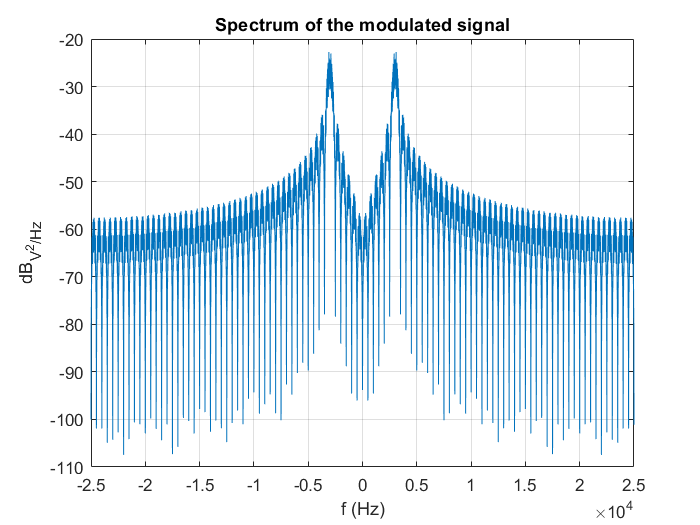

       This picture is plotteed with parameter L = 4, RECT pluse

These pictures show the similar result to spectrum of the PAM signals, but the modulated signal frequency is different.

%----------------------------------------------------------------
% output the signal to the audio card
sound(s,fs)